# Metodo delle Secanti

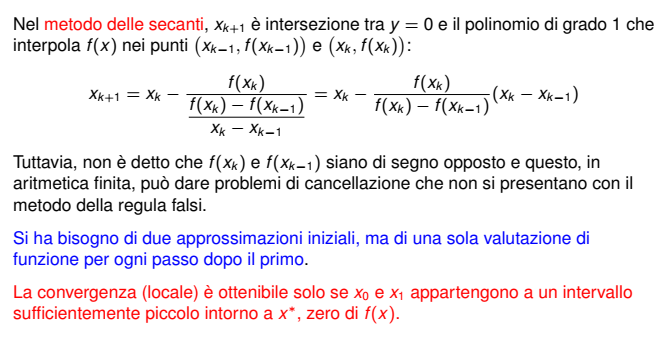

clear;
clc;

a = 4;
b = 5;


f = @(x) (exp(x/2)/2-x);

iter = @(x,xPrec) ((x - f(x)) * (x - xPrec) / (f(x) - f(xPrec)));

n = 25;
v = zeros(n,1);
v(1) = 5;
v(2) = (b+a)/2; 

for i=3:n
    v(i) = iter(v(i-1),v(i-2));
end
disp(v);

    5.0000
    4.5000
    2.5114
    6.4974
    0.0651
   -0.4191
    1.6139
   -3.2506
    8.3552
   -8.8259
  -19.6780
   39.3778
  -59.0558
   -0.0001
    0.5044
   -0.5105
    1.8836
   -3.9683
   10.0999
  -12.7329
  -10.5388
   21.0966
  -31.6178
   -0.1754
    0.8208

